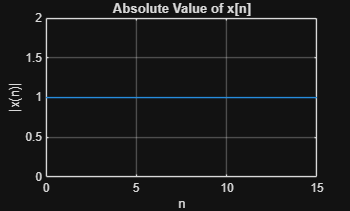

% Question 2.1 part b)

% Define fundamental period
n = 0:15;

% Generate the DT signal x[n]
x = exp(j*0.375*pi*n);

% Generating Plot
figure(1);
plot(n, abs(x));
title('Absolute Value of x[n]');
xlabel('n');
ylabel('|x(n)|');
grid on;

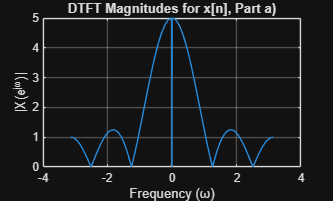

% Question 2.1 part c) plots
w = -pi:(pi/500):pi; % Frequency range

mag_a = abs(sin(5*w/2) ./ (sin(w/2) + eps)); % magnitude of a
mag_b = abs(sin(5*w/2) ./ (sin(w/2) + eps)); % magnitude of b
mag_c = abs(sin(2*w) ./ (sin(w/2) + eps)); % magnitude of c

% Plot the magnitudes
figure(1);
plot(w, mag_a);
title('DTFT Magnitudes for x[n], Part a)');
xlabel('Frequency (ω)');
ylabel('|X(e^{jω})|');
grid on;

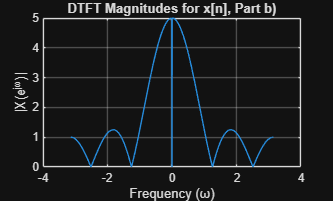


figure(2);
plot(w, mag_b);
title('DTFT Magnitudes for x[n], Part b)');
xlabel('Frequency (ω)');
ylabel('|X(e^{jω})|');
grid on;

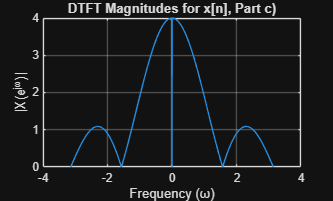


figure(3);
plot(w, mag_c);
title('DTFT Magnitudes for x[n], Part c)');
xlabel('Frequency (ω)');
ylabel('|X(e^{jω})|');
grid on;

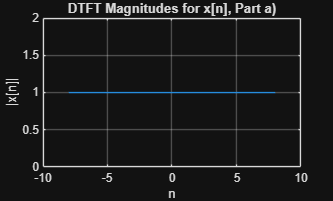

% Question 2.2A)
n = -8:8; % Frequency range
mag_a = abs(exp(j*0.5*pi*n)); % magnitude of a
mag_b = abs(cos(0.5*pi*n)); % magnitude of b

% Plot the magnitudes
figure(1);
plot(n, mag_a);
title('DTFT Magnitudes for x[n], Part a)');
xlabel('n');
ylabel('|x[n]|');
grid on;

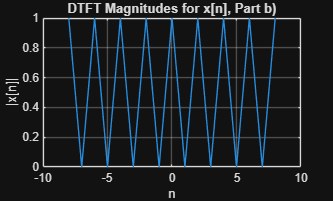


plot(n, mag_b);
title('DTFT Magnitudes for x[n], Part b)');
xlabel('n');
ylabel('|x[n]|');
grid on;

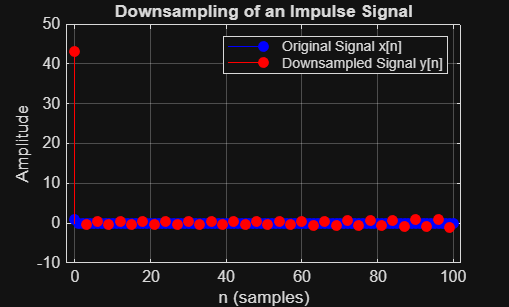

% Question 2.3
% Part a)

% 1. Create the original signal x[n] as a single impulse.
n = 0:100;
x = zeros(size(n));
x(1) = 1; % Place a single impulse at the start

% 2. Simulate the ideal anti-aliasing filter.
% The filter's cutoff frequency is at pi/3.
N_fft = 2^nextpow2(length(x));
X_fft = fft(x, N_fft);

% Create the filter's frequency response H(e^jw)
filter_freq = (0:N_fft-1) * (2*pi/N_fft);
H = zeros(1, N_fft);
H(find(filter_freq <= pi/3)) = 1;
H(find(filter_freq >= 2*pi - pi/3)) = 1; % Account for periodicity

% Apply the filter in the frequency domain
G_fft = X_fft .* H;

% Transform back to the time domain to get the filtered signal g[n]
g = ifft(G_fft);

% Apply the scaling factor
g = N_fft * g;
g = real(g(1:length(x)));

% 3. Downsample the filtered signal g[n] by a factor of 3 to get y[n].
y = g(1:3:end);

% Create a time vector for the downsampled signal
n_down = n(1:3:end);

% 4. Plot both signals on the same graph for comparison.
figure;
stem(n, x, 'b', 'filled', 'DisplayName', 'Original Signal x[n]');
hold on;
stem(n_down, y, 'r', 'filled', 'DisplayName', 'Downsampled Signal y[n]');
hold off;

title('Downsampling of an Impulse Signal');
xlabel('n (samples)');
ylabel('Amplitude');
legend('show');
grid on;